# Simulation of ground acceleration record

 Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

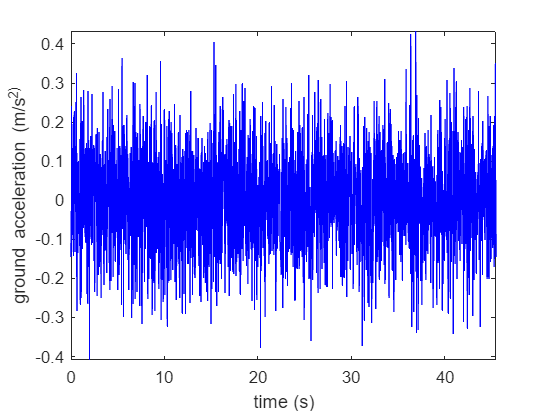

clearvars;close all;clc;

f = linspace(0,45,2048); % frequency vector
zeta = 0.5; % bandwidth of the earthquake excitation.
sigma = 0.5; % standard deviation of the excitation.
fn = 20; % dominant frequency of the earthquake excitation (Hz).
T90 = 1; % value of the envelop function at 90 percent of the duration.
eps = 0.9; % normalized duration time when ground motion achieves peak.
tn = 50; % duration of ground motion (seconds).

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

figure
plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight

set(gcf,'color','w')

## Fitting the ground acceleration record to target spectra & envelop

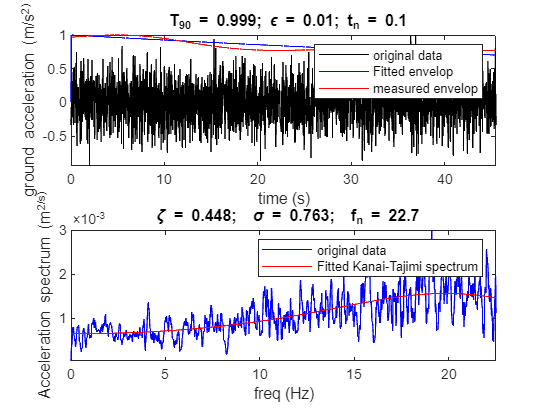

guessEnvelop=[0.33,0.43,50]; % guest for envelop 
guessKT = [20,0.5,5]; % guess for spectrum
[T90,eps,tn,zeta,sigma,fn] = fitKT(t,y,guessEnvelop,guessKT,...
    'dataPlot','yes');